% do = alpha*t+beta+gama*ph+delta*T+n
ph = [7.4
7.3
7.5
7.5
7.6
7.6
7.3
7.0
7.6
7.5
7.7
7.8
7.3
7.2
7.5
7.6
7.6
7.6
7.6
7.5
7.6
7.3
7.4
7.7
7.4
7.5
7.5
7.7
7.5
7.7
7.6
7.5
7.5
7.3
7.7
7.4
7.8
7.5
7.4
7.8
7.5
7.8
7.4
7.6
7.1
7.4
7.6
7.7
7.7
7.9
7.6
7.6
7.7
7.6
7.2
7.7
7.7
7.8
7.9
7.5
7.8
7.5
7.5
7.6
7.7
7.7
7.7
7.4
7.5
7.7
7.7
7.8
7.6
7.5
7.2
7.9
7.5
7.2
7.2
7.3
7.4
7.4
7.1
7.2
7.6
7.6
7.5
7.8
8.1
7.7
7.4
]

ph =     7.4000
    7.3000
    7.5000
    7.5000
    7.6000
    7.6000
    7.3000
    7.0000
    7.6000
    7.5000



T = [7.1
20.0
23.2
23.6
24.1
20.7
11.4
1.4
12.9
25.9
27.3
8.2
0.3
6.1
15.6
29.3
19.6
12.0
4.3
3.1
13.0
26.5
26.5
5.0
4.2
1.9
19.1
25.3
19.9
10.3
0.7
10.8
14.1
20.6
24.4
23.8
19.0
12.4
4.5
3.1
0.8
4.3
11.9
22.4
20.9
24.0
26.1
21.8
16.1
9.5
7.0
2.5
9.6
15.5
15.9
22.0
29.7
26.9
24.0
10.1
5.3
3.0
5.0
1.5
2.9
12.3
18.5
22.6
25.7
26.1
21.4
16.0
0.8
0.0
6.2
4.4
8.6
22.9
22.6
25.9
25.3
18.9
9.6
5.5
3.6
0.4
1.4
2.0
7.0
16.6
17.0
]

T =     7.1000
   20.0000
   23.2000
   23.6000
   24.1000
   20.7000
   11.4000
    1.4000
   12.9000
   25.9000



do = [13.4
9.6
8.9
8.6
8.8
9.3
11.6
14.2
11.2
8.9
8.0
12.9
15.8
12.7
11.8
8.1
9.8
10.7
14.2
14.1
11.1
13.9
8.2
13.2
13.8
14.0
9.4
8.4
9.2
11.6
14.3
11.6
10.9
9.2
8.5
8.9
10.8
11.2
13.4
13.5
14.5
14.0
11.7
9.2
9.1
8.4
8.2
8.7
10.2
11.8
12.6
13.6
11.2
10.0
9.9
8.6
7.0
8.2
8.6
11.4
12.7
13.6
13.0
14.0
13.8
11.0
10.0
8.5
8.4
8.2
9.2
10.1
14.5
14.7
13.1
14.0
12.1
9.2
8.6
8.3
8.6
9.4
11.9
12.8
13.4
15.2
14.7
14.5
12.6
10.2
7.8
]

do =    13.4000
    9.6000
    8.9000
    8.6000
    8.8000
    9.3000
   11.6000
   14.2000
   11.2000
    8.9000



time = ones(91,1);
time(:,1) = 0:90

time =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


one_1 = ones(91,1)

one_1 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1



A = [time,one_1,ph,T]

A =          0    1.0000    7.4000    7.1000
    1.0000    1.0000    7.3000   20.0000
    2.0000    1.0000    7.5000   23.2000
    3.0000    1.0000    7.5000   23.6000
    4.0000    1.0000    7.6000   24.1000
    5.0000    1.0000    7.6000   20.7000
    6.0000    1.0000    7.3000   11.4000
    7.0000    1.0000    7.0000    1.4000
    8.0000    1.0000    7.6000   12.9000
    9.0000    1.0000    7.5000   25.9000


At=A.';
AtA=At*A;
AtA_1=inv(AtA);

Aplus=AtA_1*At;
w_b = Aplus*do

w_b =    -0.0069
   15.9920
   -0.1597
   -0.2417



% unit:(mg/l)/month mg/l mg/l (mg/l)/degree C

q = A*w_b

q =    13.0947
    9.9864
    9.1742
    9.0707
    8.9270
    9.7417
   12.0302
   14.4878
   11.6060
    8.4735


r = do - q

r =     0.3053
   -0.3864
   -0.2742
   -0.4707
   -0.1270
   -0.4417
   -0.4302
   -0.2878
   -0.4060
    0.4265


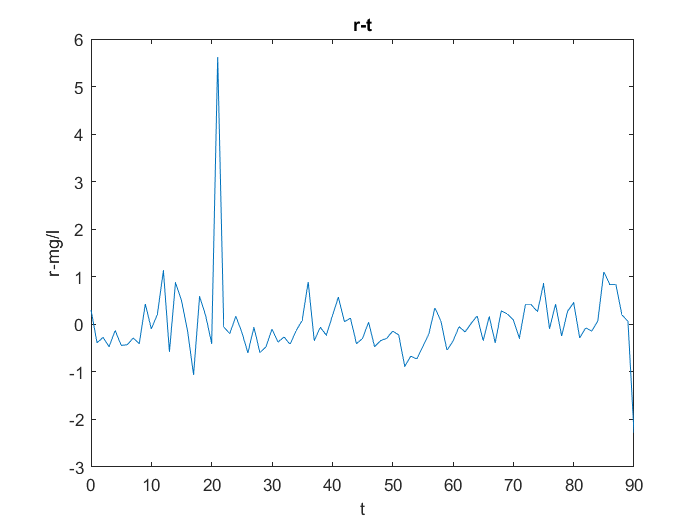


figure
plot(time(1:91,1),r(1:91,1))
title('r-t')
xlabel('t')
ylabel('r-mg/l')

mean(r)

ans = 8.5494e-13

std(r)

ans = 0.7722

isoutlier(r,'mean') 

ans = 91×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0





do

do =    13.4000
    9.6000
    8.9000
    8.6000
    8.8000
    9.3000
   11.6000
   14.2000
   11.2000
    8.9000


do_1=[do(1:21,1);do(23:end,1)]

do_1 =    13.4000
    9.6000
    8.9000
    8.6000
    8.8000
    9.3000
   11.6000
   14.2000
   11.2000
    8.9000


time_1 = ones(90,1);
time_1(:,1) = 0:89;
one_1_1 = ones(90,1);
ph_1 = [ph(1:21,1);ph(23:end,1)];
T_1 = [T(1:21,1);T(23:end,1)];
A_1 = [time_1,one_1_1,ph_1,T_1];

A = A_1;
At=A.';
AtA=At*A;
AtA_1=inv(AtA);

Aplus=AtA_1*At;
w_b = Aplus*do_1

w_b =    -0.0054
   13.3128
    0.1944
   -0.2509


q_1 = A_1*w_b

q_1 =    12.9697
    9.7079
    8.9385
    8.8328
    8.7214
    9.5691
   11.8390
   14.2846
   11.5102
    8.2234


r_1 = do_1 - q_1

r_1 =     0.4303
   -0.1079
   -0.0385
   -0.2328
    0.0786
   -0.2691
   -0.2390
   -0.0846
   -0.3102
    0.6766


r=r_1

r =     0.4303
   -0.1079
   -0.0385
   -0.2328
    0.0786
   -0.2691
   -0.2390
   -0.0846
   -0.3102
    0.6766


mean(r)

ans = -1.6491e-13

std(r)

ans = 0.4784

isoutlier(r,'mean') 

ans = 90×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0



do_2 = do_1(1:89,1)

do_2 =    13.4000
    9.6000
    8.9000
    8.6000
    8.8000
    9.3000
   11.6000
   14.2000
   11.2000
    8.9000


time_2 = ones(89,1);
time_2(:,1) = 0:88;
one_1_2 = ones(89,1);
ph_2 = ph_1(1:89,1);
T_2 = T(1:89,1)

T_2 =     7.1000
   20.0000
   23.2000
   23.6000
   24.1000
   20.7000
   11.4000
    1.4000
   12.9000
   25.9000


A_2 = [time_2,one_1_2,ph_2,T_2];

A = A_2;
At=A.';
AtA=At*A;
AtA_1=inv(AtA);

Aplus=AtA_1*At;
w_b = Aplus*do_2;
q_2 = A_2*w_b

q_2 =    12.5078
    9.9184
    9.3886
    9.3070
    9.2568
    9.9220
   11.5936
   13.4028
   11.4460
    8.8370


r_2 = do_2-q_2

r_2 =     0.8922
   -0.3184
   -0.4886
   -0.7070
   -0.4568
   -0.6220
    0.0064
    0.7972
   -0.2460
    0.0630


r=r_2

r =     0.8922
   -0.3184
   -0.4886
   -0.7070
   -0.4568
   -0.6220
    0.0064
    0.7972
   -0.2460
    0.0630


mean(r)

ans = -1.9091e-12

std(r)

ans = 1.4294

isoutlier(r,'mean') 

ans = 89×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0




do_3 = [do_2(1:22,1);do_2(24:end,1)]

do_3 =    13.4000
    9.6000
    8.9000
    8.6000
    8.8000
    9.3000
   11.6000
   14.2000
   11.2000
    8.9000


time_3 = ones(88,1);
time_3(:,1) = 0:87;
one_1_3 = ones(88,1);
ph_3 = [ph_2(1:22,1);ph_2(24:end,1)];
T_3 = [T_2(1:22,1);T_2(24:end,1)]; 
A_3 = [time_3,one_1_3,ph_3,T_3];

A = A_3;
At=A.';
AtA=At*A;
AtA_1=inv(AtA);

Aplus=AtA_1*At

Aplus =    -0.0008   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0006   -0.0006   -0.0007   -0.0005   -0.0006   -0.0007   -0.0006   -0.0005   -0.0005   -0.0004   -0.0005   -0.0005   -0.0005   -0.0005   -0.0004   -0.0003   -0.0004   -0.0004   -0.0004   -0.0003   -0.0002   -0.0003   -0.0003   -0.0003   -0.0003   -0.0002   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0003   -0.0002   -0.0002   -0.0001   -0.0001    0.0002    0.0001    0.0001    0.0001    0.0001   -0.0000    0.0000    0.0000
    0.2615    0.4763    0.0519    0.0532   -0.1584   -0.1572    0.4824    1.1221   -0.1537    0.0612   -0.3633   -0.5758    0.4898    0.7043    0.0672   -0.1438   -0.1429   -0.1419   -0.1410    0.0732   -0.1380    0.2898    0.2901    0.0785    0.0797   -0.3441    0.0834   -0.3414   -0.1276    0.0862    0.0879    0.5153   -0.3349    0.3054   -0.5450    0.0949    0.3088   -0.5420    0.0981   -0.5395    0.3137   -0.1105    0.9559    0.3183   -0.1061   -0.3176   -0.3165   -0.7413   -0.1015 

w_b = Aplus*do_3;
q_3 = A_3*w_b

q_3 =    12.4621
    9.8042
    9.2117
    9.1289
    9.0559
    9.7467
   11.5480
   13.4919
   11.3305
    8.6522


r_3 = do_3 - q_3

r_3 =     0.9379
   -0.2042
   -0.3117
   -0.5289
   -0.2559
   -0.4467
    0.0520
    0.7081
   -0.1305
    0.2478


r=r_3

r =     0.9379
   -0.2042
   -0.3117
   -0.5289
   -0.2559
   -0.4467
    0.0520
    0.7081
   -0.1305
    0.2478


mean(r)

ans = -5.2862e-13

std(r)

ans = 1.3535

isoutlier(r,'mean') 

ans = 88×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0



do_4 = [do_3(1:24,1);do_3(26:end,1)]

do_4 =    13.4000
    9.6000
    8.9000
    8.6000
    8.8000
    9.3000
   11.6000
   14.2000
   11.2000
    8.9000


time_4 = ones(87,1);
time_4(:,1) = 0:86;
one_1_4 = ones(87,1);
ph_4 = [ph_3(1:24,1);ph_3(26:end,1)];
T_4 = [T_3(1:24,1);T_3(26:end,1)]; 
A_4 = [time_4,one_1_4,ph_4,T_4];

A = A_4;
At=A.';
AtA=At*A;
AtA_1=inv(AtA);

Aplus=AtA_1*At

Aplus =    -0.0008   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0006   -0.0006   -0.0007   -0.0005   -0.0006   -0.0007   -0.0006   -0.0005   -0.0005   -0.0004   -0.0005   -0.0005   -0.0006   -0.0005   -0.0005   -0.0003   -0.0004   -0.0004   -0.0004   -0.0002   -0.0003   -0.0003   -0.0004   -0.0003   -0.0002   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0003   -0.0002   -0.0003   -0.0001   -0.0001    0.0002    0.0001    0.0001    0.0001    0.0001   -0.0000    0.0000    0.0000   -0.0000
    0.2662    0.4790    0.0541    0.0553   -0.1563   -0.1547    0.4862    1.1273   -0.1501    0.0627   -0.3620   -0.5715    0.4950    0.7086    0.0701   -0.1430   -0.1407   -0.1386   -0.1365    0.0778   -0.1349    0.2906    0.2943    0.0827   -0.3434    0.0829   -0.3410   -0.1258    0.0894    0.0896    0.5163   -0.3348    0.3048   -0.5455    0.0950    0.3099   -0.5396    0.1005   -0.5366    0.3158   -0.1095    0.9550    0.3178   -0.1071   -0.3189   -0.3172   -0.7411   -0.1004   -0.0989 

w_b = Aplus*do_4;
q_4 = A_4*w_b

q_4 =    12.6398
    9.8833
    9.2614
    9.1737
    9.0934
    9.8083
   11.6836
   13.7068
   11.4462
    8.6685


r_4 = do_4 - q_4

r_4 =     0.7602
   -0.2833
   -0.3614
   -0.5737
   -0.2934
   -0.5083
   -0.0836
    0.4932
   -0.2462
    0.2315


r=r_4

r =     0.7602
   -0.2833
   -0.3614
   -0.5737
   -0.2934
   -0.5083
   -0.0836
    0.4932
   -0.2462
    0.2315


mean(r)

ans = 2.2388e-12

std(r)

ans = 1.2838

isoutlier(r,'mean') 

ans = 87×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
